# ELEC4621 Lab 5 

***by Jason Ha (z5115925)***

## **Question 1**

In this question, we compute the magnitude spectrum of each bat echolocation sound sample and observe the frequency content for each.

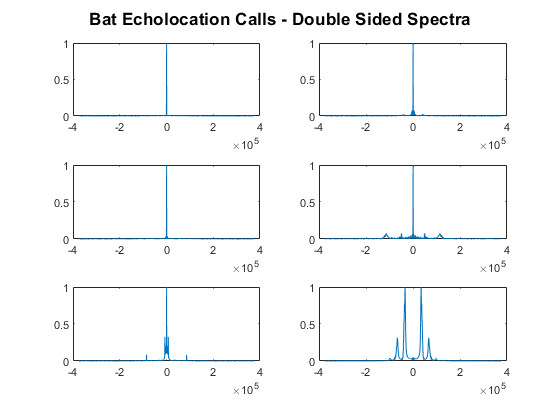

% Use 'audioread' to load the sound sample and its sampling frequency into
% the workspace. Do this for all other audio samples.
[y_mmys, Fs_mmys] = audioread("mmys.wav");
[y_pcap, Fs_pcap] = audioread("pcap.wav");
[y_pkuh, Fs_pkuh] = audioread("pkuh.wav");
[y_ppip, Fs_ppip] = audioread("ppip.wav");
[y_rcap, Fs_rcap] = audioread("rcap.wav");
[y_taegyp, Fs_taegyp] = audioread("taegyp.wav");

% Since the MATLAB's 'fft' function computes the double-sided spectrum of
% an input sequence, the frequency axis should reflect this. Since all the
% audio samples were sampled at 750000 samples/s, we can make generate a
% frequency axis for each audio sample with respect to their vector lengths
L_mmys = length(y_mmys); f_mmys = linspace(-L_mmys/2, L_mmys/2, 1024) * (Fs_mmys/L_mmys);
L_pcap = length(y_pcap); f_pcap = linspace(-L_pcap/2, L_pcap/2, 1024) * (Fs_pcap/L_pcap);
L_pkuh = length(y_pkuh); f_pkuh = linspace(-L_pkuh/2, L_pkuh/2, 1024) * (Fs_pkuh/L_pkuh);
L_ppip = length(y_ppip); f_ppip = linspace(-L_ppip/2, L_ppip/2, 1024) * (Fs_ppip/L_ppip);
L_rcap = length(y_rcap); f_rcap = linspace(-L_rcap/2, L_rcap/2, 1024) * (Fs_rcap/L_rcap);
L_taegyp = length(y_taegyp); f_taegyp = linspace(-L_taegyp/2, L_taegyp/2, 1024) * (Fs_taegyp/L_taegyp);

% Computing the FFT for each signal and then shifting the zero-frequency
% component to the centre of the array. Let the FFT block length be the
Y_mmys = abs(fftshift(fft(y_mmys, 1024)));
Y_pcap = abs(fftshift(fft(y_pcap, 1024)));
Y_pkuh = abs(fftshift(fft(y_pkuh, 1024)));
Y_ppip = abs(fftshift(fft(y_ppip, 1024)));
Y_rcap = abs(fftshift(fft(y_rcap, 1024)));
Y_taegyp = abs(fftshift(fft(y_taegyp, 1024)));

% Plot each spectra as normalised spectra and as a subplot on a 3x2 arrangement.
figure
subplot(3,2,1)
plot(f_mmys, Y_mmys / max(Y_mmys))
subplot(3,2,2)
plot(f_pcap, Y_pcap / max(Y_pcap))
subplot(3,2,3)
plot(f_pkuh, Y_pkuh / max(Y_pkuh))
subplot(3,2,4)
plot(f_ppip, Y_ppip / max(Y_ppip))
subplot(3,2,5)
plot(f_rcap, Y_rcap / max(Y_rcap))
subplot(3,2,6)
plot(f_taegyp, Y_taegyp / max(Y_taegyp))
sgtitle("Bat Echolocation Calls - Double Sided Spectra", 'fontweight', 'bold')

The frequency spectra for audio samples *mmys*, *pcap, pkuh *show a sharp harmonic at 0 Hz and audible harmonics at frequencies such as 3.4 kHz and 6.232 kHz for the *pcap *sample and at 7.6 kHz for the *rcap* sample. All other harmonics beyond 22 khz is inaudible to the human ear. When playing these audio samples with harmonics purely above 22 kHz (like the last spectrum), we only hear a click.

## Question 2

We can only estimate an approximate bandwidth of each signal based on their frequency spectra. Specifically, we look for the most prominent peak at the end of the each spectra and take that as upper bound for the bandwidth. As always, the bandwidth is the difference beween the lowest and highest frequency component in the signal sided spectrum of each sample. That is:


$$B=f_{\textrm{upper}} -f_{\textrm{lower}}$$


We can use the powerbw function to compute the bandwidth at the -3dB frequency provided we supply the input sequence and the sample rate

- *mmys* sample: $B=1\ldotp 34\;\textrm{Hz}$

- *pcap* sample: $B=513\ldotp 97\;\textrm{Hz}$

- *pkuh* sample: $B=703\ldotp 83\;\textrm{Hz}$

- *ppip* sample: $B=2059\ldotp 04\;\textrm{Hz}$

- *rcap* sample: $B=51\ldotp 42\;\textrm{Hz}$

- *taegyp* sample: $B=13898\ldotp 27\;\textrm{Hz}$

By the *Nyquist Sampling Theorem* the *minimum* required sampling frequency must be at least **double** of the bandwidths specified above. The sampling rate of 750 *ksamples/s* is more than sufficient to ensure this constraint is met.

## Question 3

The code cell below plays the sound of one of the samples. We pick, explicitly a sample with non-zero harmonic content in the audible range and those above the 22 khz range.We use the *ppip.wav* sample.

sound(y_ppip, 44100);

Since the original signals were all sampled as 750 ksamples/s, the playback of the sample requires the signal to be ***downsampled*** prior to the playback. The downsample factor is:


$$F_{\textrm{down}} =\frac{750000}{44100}\approx 17$$


## Question 4

We now wish to compute the STFT of a signal based on the specified frame size that is up to the user.  The STFT or the *Short-Time Fourier Transform* computes the FFT of small contiguous blocks of a signal. In essence, this allows us to see how the frequency content in the signal varies over time. The STFT is one of various time-frequency analysis tools and can be expressed via the following equation:


$$\textrm{STFT}\left\lbrace x\left(t\right)\right\rbrace \left(\tau \;,\omega \;\right)=\hat{x} \left(\tau \;,\omega \;\right)=\int_{\infty \;}^{\infty \;} x\left(t\right)w\left(t-\tau \;\right)e^{-j\omega \;t} \textrm{dt}$$


Where $\tau \;$ is the time where the window function, $w$ is centred at along the signal $x\left(t\right)$. The window is required as taking chunks of the signal via a sliding frame produces **discontinuities** at the ends of the frames which generates spectral leakages when the Fourier Transform of the signal chunk is performed. To ensure these leakages/ripples are minimised, a window function (such as the Hann window) is used that does NOT exhibit any discontinuities. The process with which the STFT is performed can be described by the following series of steps.

- Initialise a frame length, $F$ where $F<<L$ where $L$ is the length of the signal

- Using a *for *loop, take the first F samples of the input signal i.e. $x\left\lbrack 1\right\rbrack$ to $x\left\lbrack F\right\rbrack$

- Compute the FFT of the chunk which produces a vector. Assign vector to a 2D array.

- Move the frame to the next chunk i.e. from $x\left\lbrack 1+kF\right\rbrack$ to $x\left\lbrack F+kF\right\rbrack$ for $k$ is an integer multiple of $F$ until the end of the signal is reached.

- Use *imagesc* to plot the 2D spectrogram of the signal.

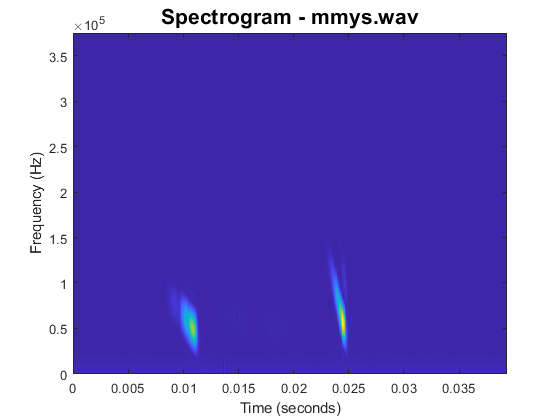

% Perform the STFT
[X_vecs, freq_axis, time_axis, chunks] = my_stft(y_mmys, 50, Fs_mmys);

% Produce the surface plot of X_vecs. The surface plot serves as the
% spectrogram of the signal.
figure
imagesc(time_axis, freq_axis, X_vecs)
colormap;

% Need to invert the frequency axis, bottom to top.
ax = gca;
ax.YDir = 'normal';

% Housekeeping for plots (title, labels etc.)
title("Spectrogram - mmys.wav", 'fontweight', 'bold', 'fontsize', 16)
xlabel("Time (seconds)")
ylabel("Frequency (Hz)")

This spectrogram reveals the signal exhibiting high amplitude components at around 5 kHz. Better resolution in the resultant spectrogram is shown by decreasing the size of the frames. However, we need to be careful as a frame size loses temporal information despite it improving the frequency resolution. The same can be said if we increase the frame length to account for a larger time window which reduces temporal accuracy but increases frequency resolution. We can now do this for the rest of the signals

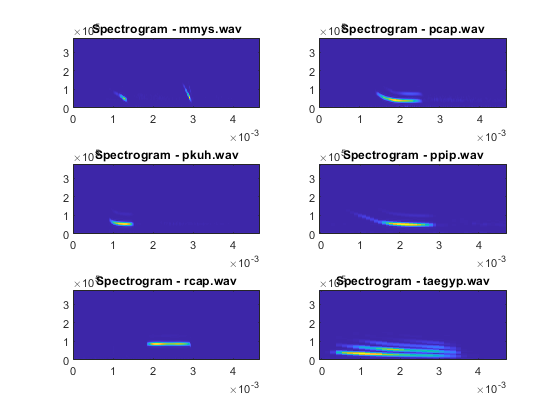

% Perform the STFT
[X_mmys, freq_axis, time_axis, chunks] = my_stft(y_mmys, 100, Fs_mmys);
[X_pcap, freq_axis, time_axis, chunks] = my_stft(y_pcap, 100, Fs_pcap);
[X_pkuh, freq_axis, time_axis, chunks] = my_stft(y_pkuh, 100, Fs_pkuh);
[X_ppip, freq_axis, time_axis, chunks] = my_stft(y_ppip, 100, Fs_ppip);
[X_rcap, freq_axis, time_axis, chunks] = my_stft(y_rcap, 100, Fs_rcap);
[X_taegyp, freq_axis, time_axis, chunks] = my_stft(y_taegyp, 100, Fs_taegyp);

% Produce the surface plot of X_vecs. The surface plot serves as the
% spectrogram of the signal.
figure
subplot(3,2,1)
imagesc(time_axis, freq_axis, X_mmys)
ax = gca;
ax.YDir = 'normal';
title("Spectrogram - mmys.wav")
subplot(3,2,2)
imagesc(time_axis, freq_axis, X_pcap)
ax = gca;
ax.YDir = 'normal';
title("Spectrogram - pcap.wav")
subplot(3,2,3)
imagesc(time_axis, freq_axis, X_pkuh)
ax = gca;
ax.YDir = 'normal';
title("Spectrogram - pkuh.wav")
subplot(3,2,4)
imagesc(time_axis, freq_axis, X_ppip)
ax = gca;
ax.YDir = 'normal';
title("Spectrogram - ppip.wav")
subplot(3,2,5)
imagesc(time_axis, freq_axis, X_rcap)
ax = gca;
ax.YDir = 'normal';
title("Spectrogram - rcap.wav")
subplot(3,2,6)
imagesc(time_axis, freq_axis, X_taegyp)
ax = gca;
ax.YDir = 'normal';
title("Spectrogram - taegyp.wav")

The amplitude characteristics at each frequency stays fairly constant throughout time. This makes sense due to the short duration of each audio sample which will not allow much variation in pitch over time. 

The use of the Hanning window also ensures each contigous block is smooth at the end of each frame and is reflected in the smoothness of the prominent regions in the spectrogram.

## **Question 5**

We now want to resample each of the following signals based on their bandwidths as was computed in *Question 2*. We wish to resample to each signals' ***minimum***** required** sampling rate as per the Nyquist sampling theorem. For ease, we'll use the resampling function *resample* that resamples at a rate of $\frac{P}{Q}$ times the original sampling rate. In our case $Q=750\;\mathrm{kHz}$ and $P$ will be the double the bandwidth values computed in *Question 2. *The following ratios will be used for each signal: